## Script name: Code to replicate analyses in Velasquez Jimenez and Abram 2024

#### Purpose of script: Produce spatial correlations maps of natural and normalised SAM indices with temperature and precipitation

#### Script author: Laura Velasquez Jimenez

#### Last updated: 03/04/2024

#### Email: laura.velasquezjimenez@anu.edu.au

#### Please cite the paper if using or re-purposing this code. 

This script requires the following imputs: 

- Spatial correlation between daily, monthly and annual natural SAM indices and temperature

- Spatial correlation between daily, montlhy and annual normalised SAM indices and temperature

- Spatial correlation between daily, monthly and annual natural SAM indices and precipitation

- Spatial correlation between daily, monthly and annual normalised SAM indices and precipitation

- Spatial correlation between monthly and annual weighted natural SAM indices and temperature

This code is written to be applicable to any set of matrices. Just replace the name of the matrices you want to plot. 

When plotting change colour palettes and colour scale limits according to the data you are plotting. 

The m_map and climate data toolboxes are need it to run the code. 

File format expected: NetCDF

%Create colour palettes
% precipitation palette
precipitation_palette = [0.3804 0.2078 0.0118 
    0.5608 0.3294 0.0667
    0.7608 0.5333 0.2745
    0.8392 0.7373 0.5294 
    0.9098 0.8549 0.7451
    0.9608 0.9333 0.8824
    1.0 1.0 1.0 
    0.8549 0.9412 0.9412
    0.6784 0.8706 0.8706
    0.4118 0.7608 0.7608
    0.2 0.6 0.6
    0.0 0.4 0.4
    0 0.3098 0.3098];
%%temperature palette
temp_palette=[0.039 0.0039 0.4314
    0.0118 0.3529 0.5804
    0.2000 0.5137 0.7216
    0.5451 0.6980 0.8000
    0.7098 0.8314 0.9098
    0.8196 0.8902 0.9412
    1.0 1.0 1.0
    0.9804 0.8863 0.8039
    0.9294 0.6784 0.5843
    0.8392 0.3922 0.3608
    0.7020 0.1137 0.2196
    0.5020 0.0196 0.1098
    0.3412 0.0118 0.0706]

temp_palette =    0.039000000000000   0.003900000000000   0.431400000000000
   0.011800000000000   0.352900000000000   0.580400000000000
   0.200000000000000   0.513700000000000   0.721600000000000
   0.545100000000000   0.698000000000000   0.800000000000000
   0.709800000000000   0.831400000000000   0.909800000000000
   0.819600000000000   0.890200000000000   0.941200000000000
   1.000000000000000   1.000000000000000   1.000000000000000
   0.980400000000000   0.886300000000000   0.803900000000000
   0.929400000000000   0.678400000000000   0.584300000000000
   0.839200000000000   0.392200000000000   0.360800000000000


%This colour palette is used when calculating differences within data
%resolutions
dif_plot=[0.5098 0.2392 0
    0.6196 0.3215 0.0627
    0.8000 0.5254 0.2078
    0.8901 0.6705 0.4196
    0.8784 0.6980 0.4941
    0.9607 0.8745 0.7764
    0.9882 0.9333 0.8706
    1.0 1.0 1.0
    0.9569 0.9294 1.0 
    0.8235 0.7725 0.9019
    0.7568 0.6431 0.9194
    0.4666 0.3254 0.6784
    0.3725 0.1529 0.7019
    0.2549 0.0509 0.5607]

dif_plot =    0.509800000000000   0.239200000000000                   0
   0.619600000000000   0.321500000000000   0.062700000000000
   0.800000000000000   0.525400000000000   0.207800000000000
   0.890100000000000   0.670500000000000   0.419600000000000
   0.878400000000000   0.698000000000000   0.494100000000000
   0.960700000000000   0.874500000000000   0.776400000000000
   0.988200000000000   0.933300000000000   0.870600000000000
   1.000000000000000   1.000000000000000   1.000000000000000
   0.956900000000000   0.929400000000000   1.000000000000000
   0.823500000000000   0.772500000000000   0.901900000000000


%This colour palette is used when calculating differences between data resolutions
dif_plot2=[0.2549 0.0509 0.5607
    0.3725 0.1529 0.7019
    0.4666 0.3254 0.6784
    0.7568 0.6431 0.9194
    0.8235 0.7725 0.9019
    0.9569 0.9294 1.0
    1.0 1.0 1.0
    0.9882 0.9333 0.8706
    0.9607 0.8745 0.7764
    0.8784 0.6980 0.4941
    0.8196 0.5882 0.3216
    0.7294 0.4667 0.1686
    0.6196 0.3215 0.0627
    0.5098 0.2392 0]

dif_plot2 =    0.254900000000000   0.050900000000000   0.560700000000000
   0.372500000000000   0.152900000000000   0.701900000000000
   0.466600000000000   0.325400000000000   0.678400000000000
   0.756800000000000   0.643100000000000   0.919400000000000
   0.823500000000000   0.772500000000000   0.901900000000000
   0.956900000000000   0.929400000000000   1.000000000000000
   1.000000000000000   1.000000000000000   1.000000000000000
   0.988200000000000   0.933300000000000   0.870600000000000
   0.960700000000000   0.874500000000000   0.776400000000000
   0.878400000000000   0.698000000000000   0.494100000000000


%Normalised daily SAM correlation with temperature
day_temp='day temp.nc'% matrix spatial correlation of daily SAM index and temperature

day_temp = 'day temp.nc'

longitude=ncread(day_temp, 'lon'); %extract longitude data
latitude=ncread(day_temp, 'lat'); %extract longitude data
longitude=double(longitude); %turn variables to number
latitude=double(latitude); %turn variables to number
corr=ncread(day_temp,'corr');% correlation values
corr=corr'%turn matrix around

corr =   -0.115336574614048  -0.115336574614048  -0.115336574614048  -0.115336574614048  -0.115336574614048  -0.115336574614048  -0.115336574614048  -0.115336574614048  -0.115336574614048  -0.115336574614048  -0.115336574614048  -0.115336574614048  -0.115336574614048  -0.115336574614048  -0.115336574614048  -0.115336574614048  -0.115336574614048  -0.115336574614048  -0.115336574614048  -0.115336574614048  -0.115336574614048  -0.115336574614048  -0.115336574614048  -0.115336574614048  -0.115336574614048  -0.115336574614048  -0.115336574614048  -0.115336574614048  -0.115336574614048  -0.115336574614048  -0.115336574614048  -0.115336574614048  -0.115336574614048  -0.115336574614048  -0.115336574614048  -0.115336574614048  -0.115336574614048  -0.115336574614048  -0.115336574614048  -0.115336574614048  -0.115336574614048  -0.115336574614048  -0.115336574614048  -0.115336574614048  -0.115336574614048  -0.115336574614048  -0.115336574614048  -0.115336574614048  -0.115336574614048  -0.11533657

%Natural daily SAM correlation with temperature
no_day_temp='no normal day temp.nc';
n_corr=ncread(no_day_temp, 'corr');
n_corr=n_corr'

n_corr =   -0.097153678536415  -0.097153678536415  -0.097153678536415  -0.097153678536415  -0.097153678536415  -0.097153678536415  -0.097153678536415  -0.097153678536415  -0.097153678536415  -0.097153678536415  -0.097153678536415  -0.097153678536415  -0.097153678536415  -0.097153678536415  -0.097153678536415  -0.097153678536415  -0.097153678536415  -0.097153678536415  -0.097153678536415  -0.097153678536415  -0.097153678536415  -0.097153678536415  -0.097153678536415  -0.097153678536415  -0.097153678536415  -0.097153678536415  -0.097153678536415  -0.097153678536415  -0.097153678536415  -0.097153678536415  -0.097153678536415  -0.097153678536415  -0.097153678536415  -0.097153678536415  -0.097153678536415  -0.097153678536415  -0.097153678536415  -0.097153678536415  -0.097153678536415  -0.097153678536415  -0.097153678536415  -0.097153678536415  -0.097153678536415  -0.097153678536415  -0.097153678536415  -0.097153678536415  -0.097153678536415  -0.097153678536415  -0.097153678536415  -0.097153

small_lat=latitude(361:721)% to stipple the negatives, I subset latitude to the southern hemisphere

small_lat =                    0
  -0.250000000000000
  -0.500000000000000
  -0.750000000000000
  -1.000000000000000
  -1.250000000000000
  -1.500000000000000
  -1.750000000000000
  -2.000000000000000
  -2.250000000000000


%calculate differences between matrices. Replace matrices names with the
%matrices you are working with.
outputName = 'day';
difference = calculateDifference(corr, n_corr, outputName);
%identify the negatives
daily_result = identify_negative_cells(corr, n_corr);

%Annual SAMs
%First normal year sam
year='year temp.nc'

year = 'year temp.nc'

y_corr=ncread(year, 'corr')

y_corr =   -0.121147550642490  -0.124676249921322  -0.129641681909561  -0.135353639721870  -0.139453664422035  -0.141482383012772  -0.142719179391861  -0.143725052475929  -0.144143536686897  -0.143746763467789  -0.143128380179405  -0.145407825708389  -0.147656664252281  -0.150039777159691  -0.154022976756096  -0.158016085624695  -0.161213174462318  -0.164237275719643  -0.167170479893684  -0.168668165802956  -0.168847978115082  -0.168600469827652  -0.168499454855919  -0.166946694254875  -0.163363039493561  -0.159995988011360  -0.156945809721947  -0.152835130691528  -0.147925928235054  -0.142850607633591  -0.136876344680786  -0.130400002002716  -0.126031428575516  -0.121504381299019  -0.114449113607407  -0.104436531662941  -0.091419458389282  -0.074490569531918  -0.055342677980661  -0.032074768096209  -0.010702741332352   0.007011483889073   0.014484933577478   0.018127314746380   0.029041891917586   0.044475626200438   0.049696817994118   0.054588720202446   0.046599999070168   0.044764

y_corr=y_corr'

y_corr =   -0.121147550642490  -0.121147550642490  -0.121147550642490  -0.121147550642490  -0.121147550642490  -0.121147550642490  -0.121147550642490  -0.121147550642490  -0.121147550642490  -0.121147550642490  -0.121147550642490  -0.121147550642490  -0.121147550642490  -0.121147550642490  -0.121147550642490  -0.121147550642490  -0.121147550642490  -0.121147550642490  -0.121147550642490  -0.121147550642490  -0.121147550642490  -0.121147550642490  -0.121147550642490  -0.121147550642490  -0.121147550642490  -0.121147550642490  -0.121147550642490  -0.121147550642490  -0.121147550642490  -0.121147550642490  -0.121147550642490  -0.121147550642490  -0.121147550642490  -0.121147550642490  -0.121147550642490  -0.121147550642490  -0.121147550642490  -0.121147550642490  -0.121147550642490  -0.121147550642490  -0.121147550642490  -0.121147550642490  -0.121147550642490  -0.121147550642490  -0.121147550642490  -0.121147550642490  -0.121147550642490  -0.121147550642490  -0.121147550642490  -0.121147

% then no normal year sam
no_year='no normal year temp.nc'

no_year = 'no normal year temp.nc'

n_y_corr=ncread(no_year, 'corr')

n_y_corr =   -0.099450722336769  -0.093532450497150  -0.091364167630672  -0.093955487012863  -0.098061442375183  -0.099273644387722  -0.099023468792439  -0.098367527127266  -0.097434826195240  -0.095921970903873  -0.093809477984905  -0.095149733126163  -0.098564743995667  -0.101884789764881  -0.106573380529881  -0.111251093447208  -0.115300141274929  -0.119152978062630  -0.122704163193703  -0.124741405248642  -0.125430107116699  -0.125527426600456  -0.125759676098824  -0.124892659485340  -0.121747560799122  -0.118963219225407  -0.116830483078957  -0.114037945866585  -0.111303992569447  -0.108704961836338  -0.103422850370407  -0.097200155258179  -0.092189341783524  -0.086614347994328  -0.078443698585033  -0.066646389663219  -0.050182878971100  -0.028042001649737  -0.002864902606234   0.026249226182699   0.048609975725412   0.067934237420559   0.078708492219448   0.085873879492283   0.097662515938282   0.111203804612160   0.116208627820015   0.120969310402870   0.108730748295784   0.1033

n_y_corr=n_y_corr'

n_y_corr =   -0.099450722336769  -0.099450722336769  -0.099450722336769  -0.099450722336769  -0.099450722336769  -0.099450722336769  -0.099450722336769  -0.099450722336769  -0.099450722336769  -0.099450722336769  -0.099450722336769  -0.099450722336769  -0.099450722336769  -0.099450722336769  -0.099450722336769  -0.099450722336769  -0.099450722336769  -0.099450722336769  -0.099450722336769  -0.099450722336769  -0.099450722336769  -0.099450722336769  -0.099450722336769  -0.099450722336769  -0.099450722336769  -0.099450722336769  -0.099450722336769  -0.099450722336769  -0.099450722336769  -0.099450722336769  -0.099450722336769  -0.099450722336769  -0.099450722336769  -0.099450722336769  -0.099450722336769  -0.099450722336769  -0.099450722336769  -0.099450722336769  -0.099450722336769  -0.099450722336769  -0.099450722336769  -0.099450722336769  -0.099450722336769  -0.099450722336769  -0.099450722336769  -0.099450722336769  -0.099450722336769  -0.099450722336769  -0.099450722336769  -0.0994

%calculate differences between matrices. Replace matrices names with the
%matrices you are working with.
outputName = 'ndayyear';
difference = calculateDifference(corr, y_corr, outputName);
%identify the negatives
ndayyear_result = identify_negative_cells(corr, y_corr);

%%%%%Figures. Maps showing spatial correlation of variables and SAM indices. Change matrices and colour palettes names accordingly
%spatial correlation maps. Replace with data sets
SAM=tiledlayout(1,1)

SAM =   TiledChartLayout with properties:

    TileArrangement: 'fixed'
           GridSize: [1 1]
            Padding: 'loose'
        TileSpacing: 'loose'

  Show all properties


%E.g.Spatial correlation of Normalised daily SAM index with temperature
nexttile
axesm('MapProjection', 'Robinson', 'MapLatLimit',[-90 0], 'MapLonLimit',[0 360], 'Grid','on' );
framem; 
axis off;
% Plot the data on the map
pcolorm(latitude, longitude, corr)
colormap(temp_palette);
h=colorbar, clim([-0.6 0.6]);% 

h =   ColorBar with properties:

    Location: 'eastoutside'
      Limits: [-0.577823817729950 0.465175986289978]
    FontSize: 9
    Position: [0.887380952380952 0.394444444444444 0.028571428571429 0.246111111111111]
       Units: 'normalized'

  Show all properties


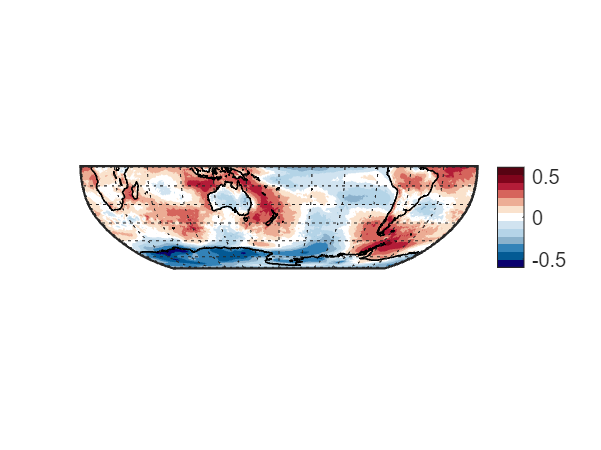

load coastlines;  % Load coastline data
plotm(coastlat, coastlon, 'k', 'LineWidth', 0.8);

%Plot differences within data resolution. E.g. Daily normalised SAM vs.
%natural SAM
%%variables names and colour scale accordingly
differencesplot=tiledlayout(1,1)

differencesplot =   TiledChartLayout with properties:

    TileArrangement: 'fixed'
           GridSize: [1 1]
            Padding: 'loose'
        TileSpacing: 'loose'

  Show all properties


nexttile
axesm('MapProjection', 'Robinson', 'MapLatLimit',[-90 0], 'MapLonLimit',[0 360] );
framem;
axis off;
pcolorm(latitude, longitude,  day);% Here replace differences matrix
stipplem(small_lat, longitude, daily_result, 'density', 125) % here replace with negat
colormap(dif_plot);
colorbar;
h=colorbar, clim([-0.2 0.2]);% for within data resolution differences 0.12, for difference between data resolution 0.02 

h =   ColorBar with properties:

    Location: 'eastoutside'
      Limits: [-0.200000000000000 0.200000000000000]
    FontSize: 9
    Position: [0.875476190476191 0.396428571428571 0.028571428571429 0.242142857142857]
       Units: 'normalized'

  Show all properties


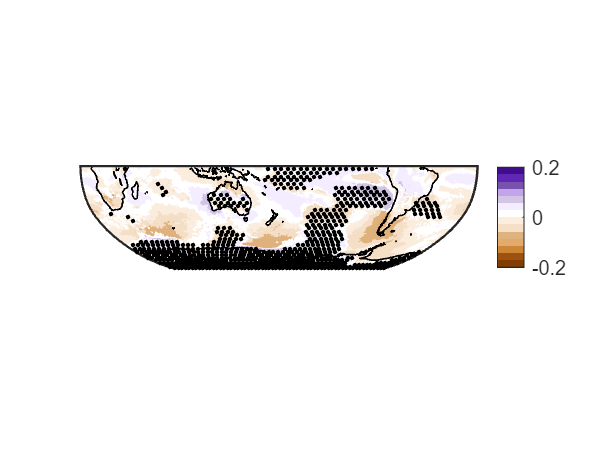

load coastlines;  % Load coastline data
plotm(coastlat, coastlon, 'k', 'LineWidth', 0.8);


%Plot differences between data resolutions. E.g. Daily and annual natural
%SAM
%change variables names and colour scale accordingly
differencesplot=tiledlayout(1,1)

differencesplot =   TiledChartLayout with properties:

    TileArrangement: 'fixed'
           GridSize: [1 1]
            Padding: 'loose'
        TileSpacing: 'loose'

  Show all properties


nexttile
axesm('MapProjection', 'Robinson', 'MapLatLimit',[-90 0], 'MapLonLimit',[0 360] );
framem;
axis off;
pcolorm(latitude, longitude,  ndayyear);% Here replace differences matrix
stipplem(small_lat, longitude, ndayyear_result, 'density', 125) % here replace with negat
colormap(dif_plot2);
colorbar;
h=colorbar, clim([-0.02 0.02]);% for within data resolution differences 0.12, for difference between data resolution 0.02 

h =   ColorBar with properties:

    Location: 'eastoutside'
      Limits: [-0.020000000000000 0.020000000000000]
    FontSize: 9
    Position: [0.863571428571429 0.398412698412698 0.028571428571429 0.238174603174603]
       Units: 'normalized'

  Show all properties


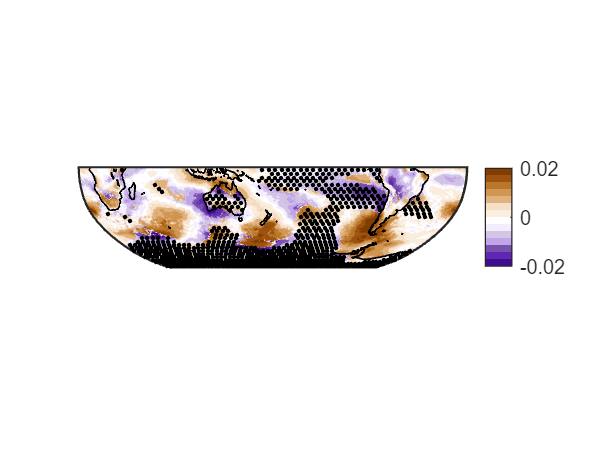

load coastlines;  % Load coastline data
plotm(coastlat, coastlon, 'k', 'LineWidth', 0.8);

function result = identify_negative_cells(matrix1, matrix2)%This function finds the negative cells that are consistent between both
%matrices
    [rows, cols] = size(matrix1);
    result = false(rows, cols); % Initialize the result matrix as logical false

    indices = (matrix1 < -0.05) & (matrix2 < -0.05);
    result(indices) = true; % Set the corresponding indices to true
    
    result= result(361:721,:);%because the data is from the hole globe
end

%this function calculates the difference between the matrices
function difference = calculateDifference(matrix1, matrix2, outputName)
    % Create a logical matrix indicating cells with different symbols
    differentCells = matrix1 .* matrix2 < 0;
    
    % Replace the values in different cells with zeros
    matrix1(differentCells) = 0;
    matrix2(differentCells) = 0;
    
    % Multiply all the negative numbers by -1
    multiplier = -1;
    matrix1(matrix1 < 0) = matrix1(matrix1 < 0) * multiplier;
    matrix2(matrix2 < 0) = matrix2(matrix2 < 0) * multiplier;
    
    % Subtract the modified matrices
    difference = matrix1 - matrix2;
    % Save the result with the specified output name
    assignin('caller', outputName, difference);
end